robot = importrobot('sawyer.urdf', DataFormat='column');

q_with_screen = randomConfiguration(robot)

q_with_screen =    -2.8188
   -1.8949
    0.6106
   -3.0117
    1.7236
   -0.5123
   -1.8515
    1.5910


q = q_with_screen([1 3:8]);

body_names.EE = 'right_hand';
body_names.S = 'base';
body_names.E = 'right_l3';
body_names.W = 'right_wrist';

tf_E = getTransform(robot, [q(1); 0; q(2:end)],body_names.E);
tf_W = getTransform(robot, [q(1); 0; q(2:end)],body_names.W);
S = [0;0;0];
E = tform2trvec(tf_E)';
W = tform2trvec(tf_W)';

tf_EE = getTransform(robot, ...
    [q(1); 0; q(2:end)],body_names.EE);
T = tform2trvec(tf_EE)'

T =    -0.5343
   -0.3175
    0.3888


R = tform2rotm(tf_EE)

R =    -0.7011    0.1004   -0.7060
   -0.0996    0.9666    0.2363
    0.7061    0.2360   -0.6676



% SEW_type = "Conventional"
% psi = conv_sew(S, E, W, [0;0;1])

SEW_type = "Stereographic"

SEW_type = "Stereographic"

psi = stereo_sew(S, E, W, [0;0;-1], [1;0;0])

psi = -2.1420


GC = [-1 -1 -1];
GC([q(2) q(4) q(6)] >= 0) = 1

GC =      1     1    -1


[qq_with_screen, SEW_R, solInfo] = mat_iter_IK(R, T, SEW_type, psi, GC, robot, body_names, S, W, robot.homeConfiguration)

qq_with_screen =     4.2759
         0
   -0.0000
    4.8370
    1.2105
   -1.9221
   -0.6531
    1.8380


SEW_R =    -0.2805    0.7527   -0.5956
   -0.6344   -0.6110   -0.4734
   -0.7203    0.2451    0.6489


solInfo = struct with fields:
              Iterations: 111
       NumRandomRestarts: 1
    ConstraintViolations: [1×2 struct]
                ExitFlag: 1
                  Status: 'success'


qq = qq_with_screen([1 3:8]);

tf_EE = getTransform(robot, ...
    qq_with_screen, body_names.EE);
TT = tform2trvec(tf_EE)'

TT =    -0.5343
   -0.3175
    0.3888


RR = tform2rotm(tf_EE)

RR =    -0.7011    0.1004   -0.7060
   -0.0996    0.9666    0.2363
    0.7061    0.2360   -0.6676



GCGC = [-1 -1 -1];
GCGC([qq(2) qq(4) qq(6)] >= 0) = 1

GCGC =     -1     1    -1


[qq_with_screen,  solInfo] = mat_iter_IK_no_SEW(R, T, GC, robot, body_names, robot.homeConfiguration)

qq_with_screen =    -2.0073
         0
   -0.0000
   -1.4462
    1.2105
   -1.9221
   -0.6531
    1.8380


solInfo = struct with fields:
              Iterations: 107
       NumRandomRestarts: 1
    ConstraintViolations: [1×2 struct]
                ExitFlag: 4
                  Status: 'success'


qq = qq_with_screen([1 3:8]);

tf_EE = getTransform(robot, ...
    qq_with_screen, body_names.EE);
TT = tform2trvec(tf_EE)'

TT =    -0.5343
   -0.3175
    0.3888


RR = tform2rotm(tf_EE)

RR =    -0.7011    0.1004   -0.7060
   -0.0996    0.9666    0.2363
    0.7061    0.2360   -0.6676



GCGC = [-1 -1 -1];
GCGC([qq(2) qq(4) qq(6)] >= 0) = 1

GCGC =     -1     1    -1


show(robot, qq_with_screen, 'Visuals','on')

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties




hold on
show(robot, q_with_screen, 'Visuals','on')

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


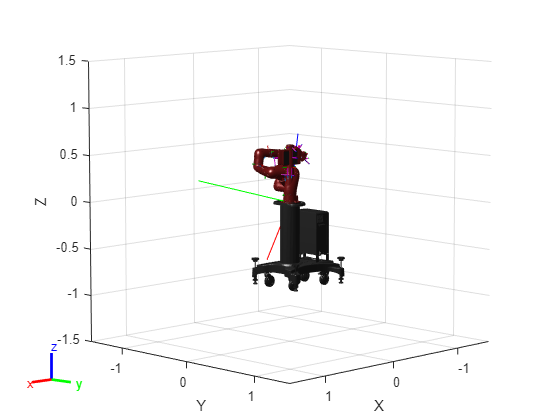

plotTransforms([0 0 0], rotm2quat(SEW_R))
hold off